# Parameter distributions and clustering

## IKtof

### Parameter density estimation - IKtof

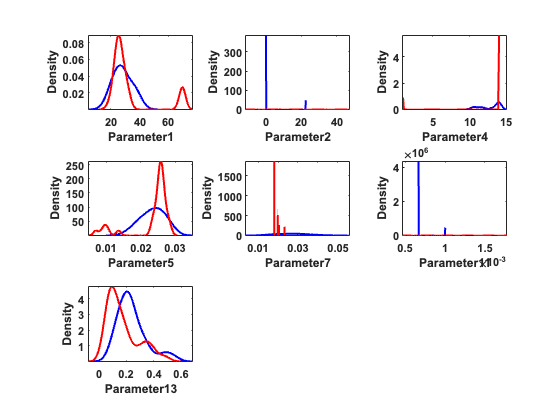

pktof = readtable("exp42_pktof.csv");
pidx = unique(pktof.param);

for i=1:length(pidx)
    psub = pktof(pktof.param==pidx(i),:);
    psub_wt = psub(string(psub.Group)=="WT",:);
    psub_ko = psub(string(psub.Group)=="Mgat1KO",:);

    [f1,xi1] = ksdensity(psub_wt.value);
    [f2,xi2] = ksdensity(psub_ko.value);
    
    subplot(3,3,i)
    plot(xi1,f1, 'Color','blue', 'LineWidth',2)
    hold on
    plot(xi2,f2, 'Color','red', 'LineWidth',2)
    hold off
    axis tight
    xlabel(strcat('Parameter', num2str(pidx(i))))
    ylabel('Density')
    set(gca, 'FontName','Arial', 'FontSize',11, 'FontWeight','bold')
end

### Clustering - PCA

% data modification
nrow = size(pktof,1)/length(pidx);
pktof2 = array2table(NaN(nrow,length(pidx)+1));
pktof2.Properties.VariableNames(1) = {'Group'};
pktof2.Group = pktof(pktof.param==pidx(1),:).Group;

for i=1:length(pidx)
    pktof2.Properties.VariableNames(i+1) = {strcat('P',num2str(pidx(i)))};
    pktof2(:,i+1)= pktof(pktof.param==pidx(i),'value');
end

[coeff,score,latent] = pca(table2array(pktof2(:,2:end)));

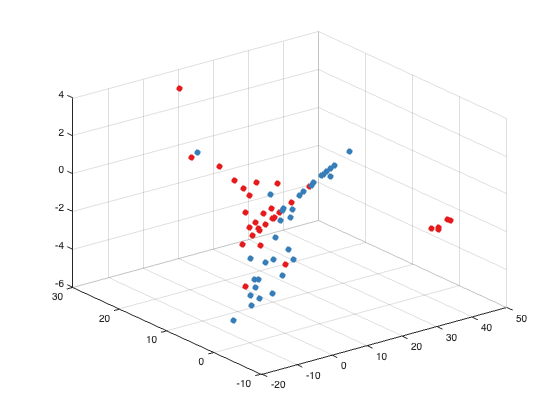

g = NaN(nrow,1);
g(pktof2.Group == "Mgat1KO") = 1;
g(pktof2.Group == "WT") = 2;
c = brewermap(length(unique(g)),'Set1');
s = scatter3(score(:,1),score(:,2),score(:,3), 'filled', 'CData',c(g,:));

% legend("WT","Mgat1KO")

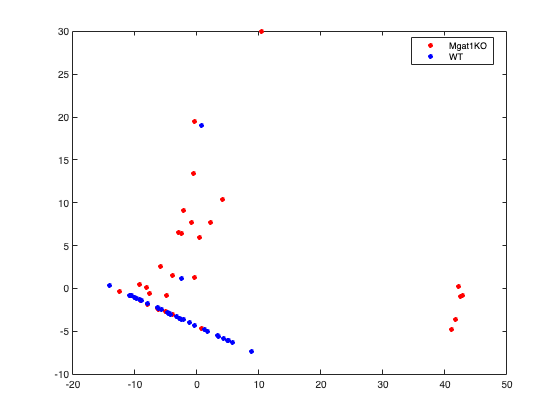

g = categorical(pktof2.Group);
gscatter(score(:,1),score(:,2),g, 'rb');

## IKslow1